# Extended Kalman Filter Estimation

clear 
close all
clc

rng('default')

## Set Path

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("Optimization/ConsOpt");
addpath("simulation/SimulationData");

Urban = 0; % by default set it to 0, constrained problem only in highway
real_meas = 0; 
max_time = 25;
min_time = 0.5;
Con = 0; % set to 1 if dealing with a constrained estimation problem

## Generate Measurement and Ground Truth Datasets

[ymeas_camera,ymeas_radar,N,time_vec,GT_state,min_index,max_index,~,~] = get_meas(Con,Urban,real_meas,min_time,max_time);

## Filtering Algorithm

### Parameters of the Algorithm

nz = 5; % number of states
ny = 4; % number of measured output
nu = 2; % number of inputs (disturbances)
Ts = 0.1; % Filter/sensors sampling time

#### Camera Covariance Matrix

As a general rule, lower values than radar

camera_x_var = 150; % better if higher
camera_y_var = 10; % better if lower
camera_v_x_var = 60; % better if higher
camera_v_y_var = 20; % better if lower
R_camera = diag([camera_x_var,camera_y_var,camera_v_x_var,camera_v_y_var])*eye(ny);

#### Radar Covariance Matrix

Higher values than camera

radar_x_var = 30; % better if lower
radar_y_var = 20; % better if higher
radar_v_x_var = 10; % better if lower
radar_v_y_var = 90; % better if higher
R_radar = diag([radar_x_var,radar_y_var,radar_v_x_var,radar_v_y_var])*eye(ny);

#### Process Covariance

long_acc_var = 1e-1;
ang_acc_var = 1e-1;
Q = diag([long_acc_var,ang_acc_var])*eye(nu);

#### Initial Guess

x0 = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);...
      ymeas_radar(4,1);0.1]; % initial state estimate

P0 = 1e3*eye(nz); % initial state covariance matrix

### Estimation Routine

z_est = zeros(nz,N); % array to store estimated state
z_est(:,1) = x0; % initial guess
Computational_time = zeros(N,1); % array storing computational time for each estimation

for ind = 2:length(time_vec)
    tic
    [z_est(:,ind),~] = EKF(ymeas_radar(:,ind),ymeas_camera(:,ind),z_est(:,ind-1),Ts,Q,R_radar,R_camera,P0);
    Computational_time(ind-1,1) = toc;
end

mean_computational_time = mean(Computational_time(1: end-1))

mean_computational_time = 1.3896e-04

## Plot Results

### Relative Position

#### $x$ - Coordinate

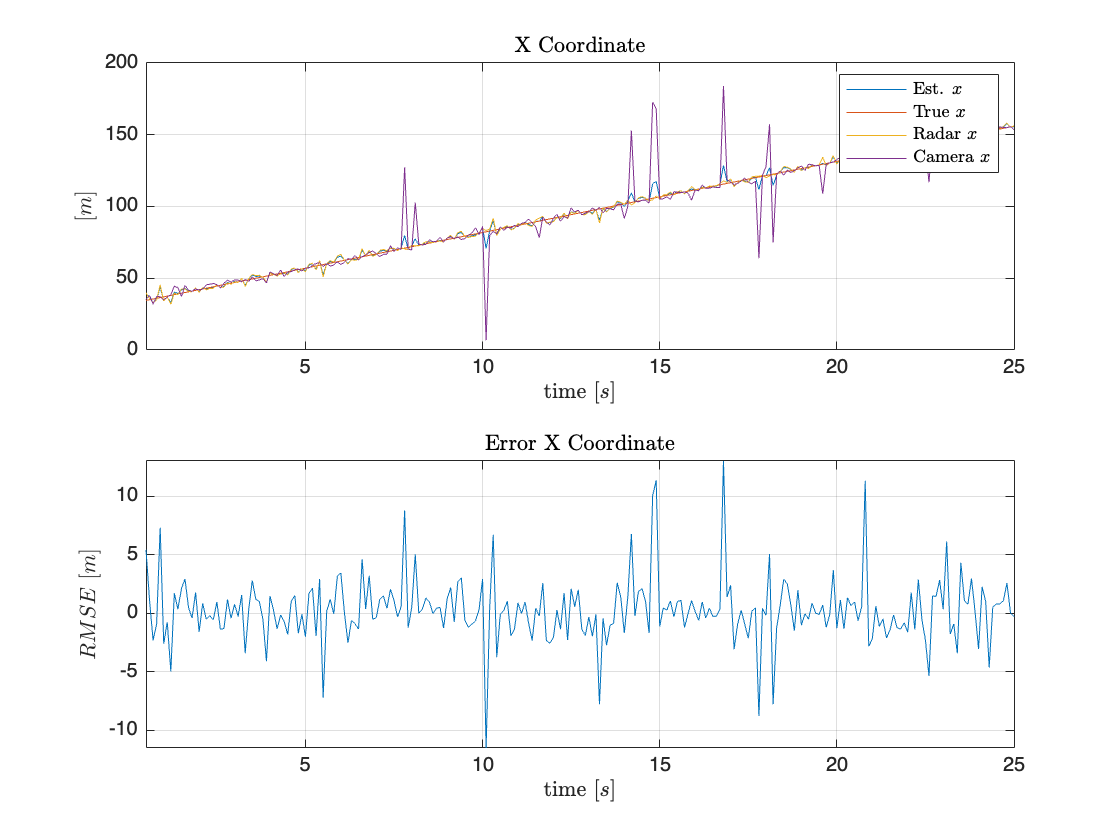

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(1,:)), hold on
plot(time_vec,GT_state(:,1)), hold on
plot(time_vec,ymeas_radar(1,:)),hold on
plot(time_vec,ymeas_camera(1,:))
title('X Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $x$','True $x$','Radar $x$','Camera $x$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(1,:)-GT_state(:,1)'))
title('Error~X Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;

xlim([min_time max_time]);
hold off

#### 
$$x-\textrm{RMSE}$$


x_rmse = rmse(z_est(1,:),GT_state(:,1)')

x_rmse = 2.7692

#### $y$ - Coordinate

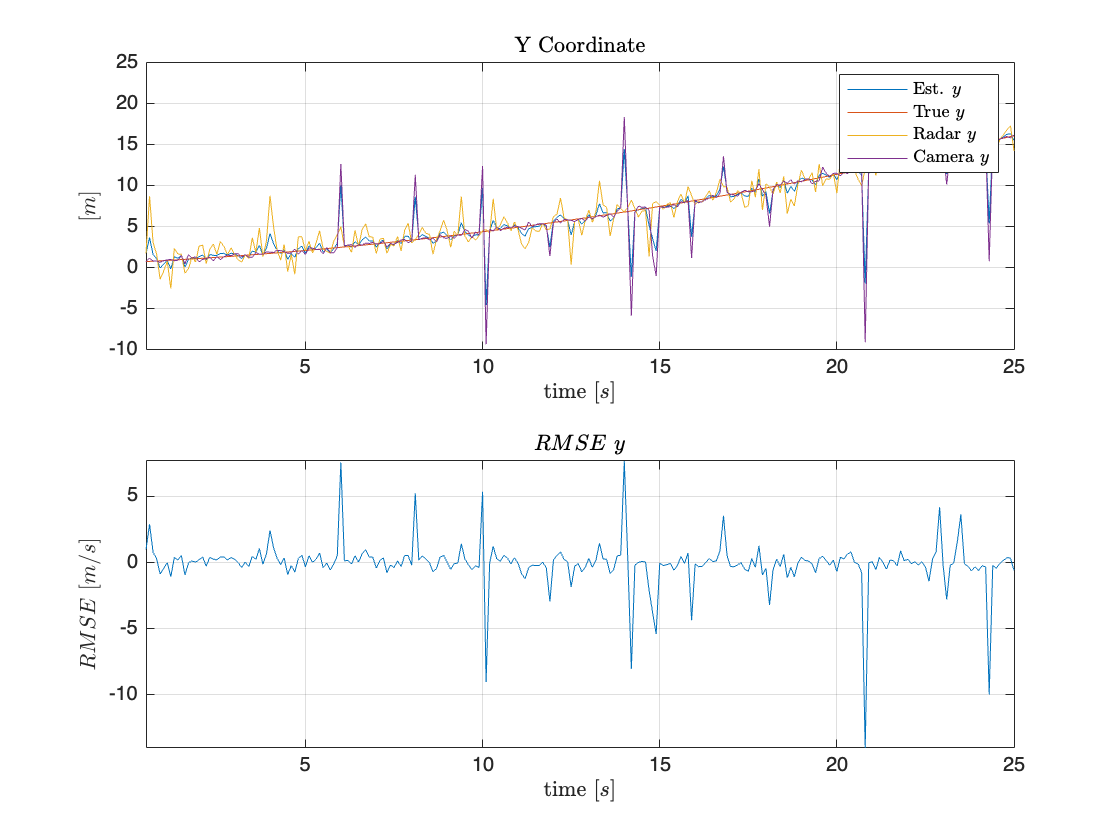

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(2,:)), hold on
plot(time_vec,GT_state(:,2)), hold on
plot(time_vec,ymeas_radar(2,:)),hold on
plot(time_vec,ymeas_camera(2,:))
title('Y Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $y$','True $y$','Radar $y$','Camera $y$','Interpreter','latex')
ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(2,:)-GT_state(:,2)'))
title('$RMSE~y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off

#### 
$$y-\textrm{RMSE}$$


y_rmse = rmse(z_est(2,:),GT_state(:,2)')

y_rmse = 1.8286

### Velocities

#### 
$$v_x$$


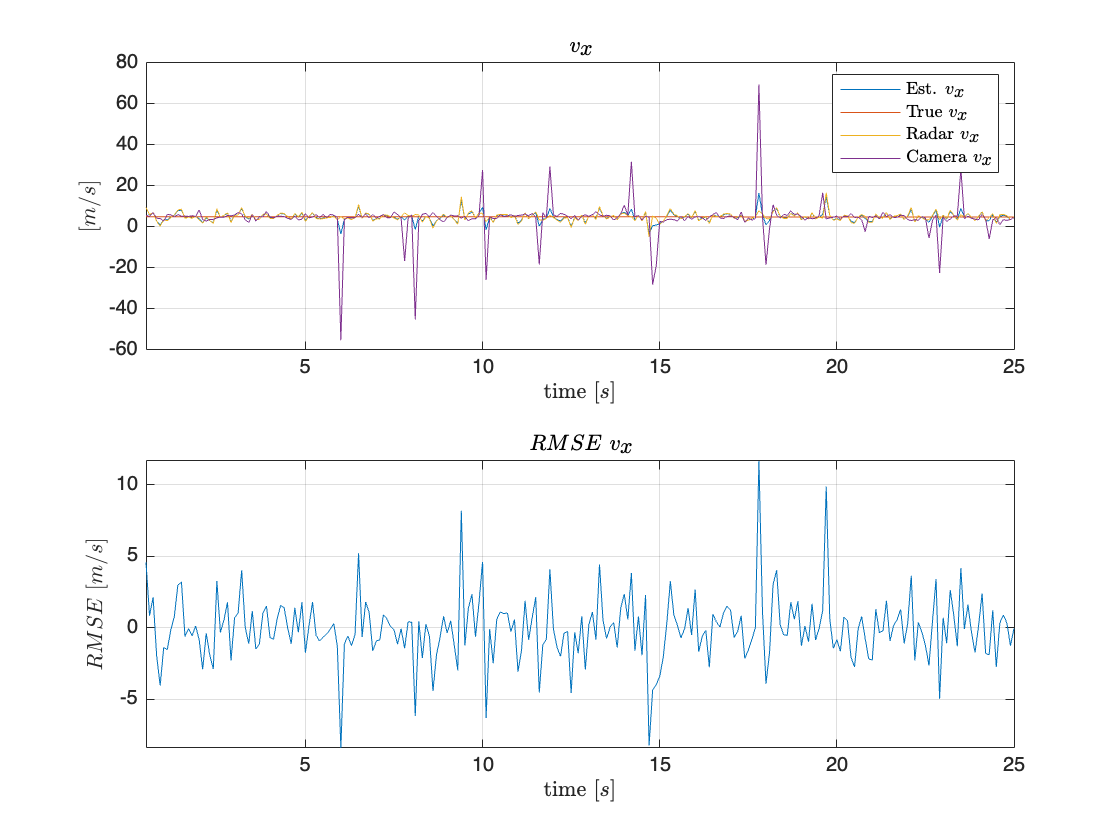

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(3,:)), hold on
plot(time_vec,GT_state(:,3)), hold on
plot(time_vec,ymeas_radar(3,:)),hold on
plot(time_vec,ymeas_camera(3,:))
title('$v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_x$','True $v_x$','Radar $v_x$','Camera $v_x$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(3,:)-GT_state(:,3)')), hold on
title('$RMSE~v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m/s]$','Interpreter','latex')

linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$v_x -\textrm{RMSE}$$


v_x_rmse = rmse(z_est(3,:),GT_state(:,3)')

v_x_rmse = 2.2880

#### 
$$v_y$$


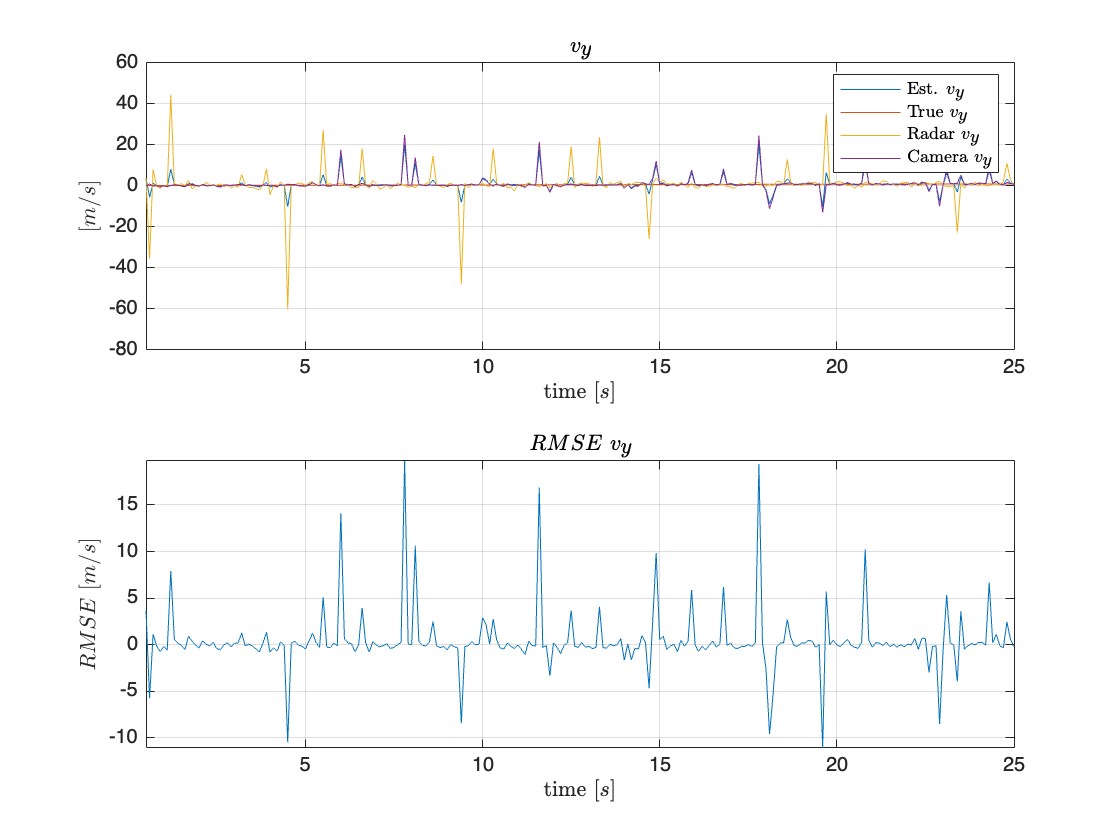

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(4,:)), hold on
plot(time_vec,GT_state(:,4)), hold on
plot(time_vec,ymeas_radar(4,:)),hold on
plot(time_vec,ymeas_camera(4,:))
title('$v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_y$','True $v_y$','Radar $v_y$','Camera $v_y$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(4,:)-GT_state(:,4)'))
title('$RMSE~v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$v_{y\;} -\textrm{RMSE}$$


v_y_rmse = rmse(z_est(4,:),GT_state(:,4)')

v_y_rmse = 3.2389

#### Yaw Rate

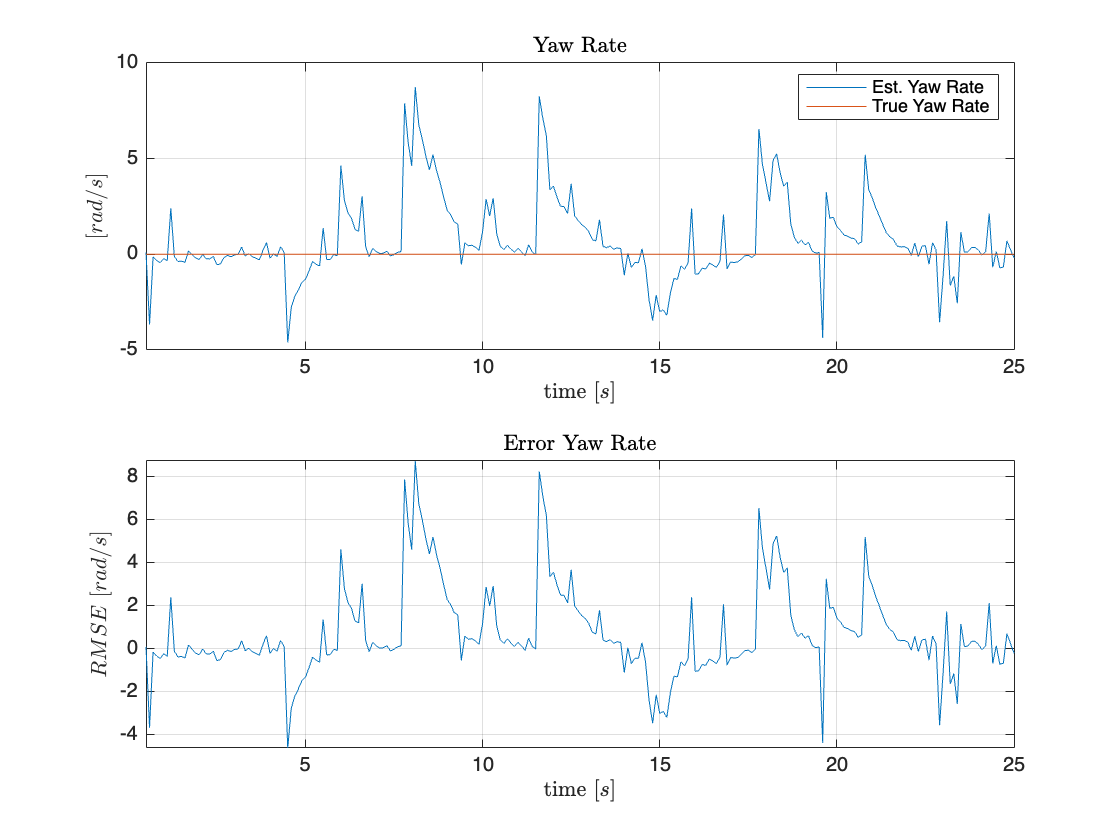

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(5,:)), hold on
plot(time_vec,GT_state(:,5))
title('Yaw Rate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s]$','Interpreter','latex')
legend('Est. Yaw Rate','True Yaw Rate')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(5,:)-GT_state(:,5)'))
title('Error Yaw Rate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$ RMSE~[rad/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$\textrm{Yaw}\;\textrm{Rate}-\textrm{RMSE}$$


yaw_rate_rmse = rmse(z_est(5,:),GT_state(:,5)')

yaw_rate_rmse = 2.2041

rmse_tot = [x_rmse; y_rmse; v_x_rmse; v_y_rmse; yaw_rate_rmse]

rmse_tot =     2.7692
    1.8286
    2.2880
    3.2389
    2.2041
